# **Figure 4**

This m-file is written according  to  the paper entitled :

 "**How Many Fixed Phase Shifters Are Needed in a Hybrid Beamforming Structure?**" 

you can see the paper on this link: 

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 03/07/2021

By Jamal Beiranvand

clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
 addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions' )) % Add path of the "Functions" folder.

K=20;                           % number of users
NPS=5:2:11;                     % Number of Phase shifters  
Txz = 12;                       % Number of the transmitter antennas on z axis
Txy =12;                      % Number of the transmitter antennas on y axis
Rxz = 1;                       % Number of the receiver antennas on z axis
Rxy = 1;                       % Number of the receiver antennas on y axis
% Ns  = 1;                       % Number of data streams
% NrfTx = 9;                     % Number of RF chains at BS
Ncl =10;                       % Number of Channel clusters(Scatters)
Nray= 5;                       % Number of rays in each cluster
AngSpread = 10;       % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
TxSector=[60 360];
RxSector=[20 360];
SNR_dB = -10:2:20;             % Signal to noise ratio in dB
realization = 100;              % Iteration of simulation
%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10);        
%% Allocate memory space for matrices
SumR_ZF=zeros(length(NPS),realization);
R_ZF1=zeros(length(NPS),realization);
R_ZF2=zeros(length(NPS),realization);
R_ZF3=zeros(length(NPS),realization);
R_ZF4=zeros(length(NPS),realization);
%%
[Setb1,Sb1]=GenUniqueSet(NPS(1));
[Setb2,Sb2]=GenUniqueSet(NPS(2));
[Setb3,Sb3]=GenUniqueSet(NPS(3));
[Setb4,Sb4]=GenUniqueSet(NPS(4));
% [Setb5,Sb5]=GenUniqueSet(NPS(5));
for r=1:length(SNR_dB)
%     Setb=[];    
    formatSpec = 'Step %i of %i \n';
    fprintf(formatSpec,r,length(SNR_dB))
    Snr=SNR(r);
    for reali=1:realization
        % generate channel
        [H,At,Ar,~]=MU_Channel(Tx,K,Ncl,'Nray',Nray,'AngSpread',AngSpread);
         G= diag(ones(K,1))*sqrt(Snr);   
        % Full Digital ZF beamforming
        Fzf=ZF_Down(H);        
        SumR_ZF(r,reali)=SumRate(H,Fzf,G);
         % Implement 
        [FRF_ZF,~]=MUMISO_DownModified(Fzf,Setb1,Sb1);
        FRF_ZF=FRF_ZF/sqrt(sum(sum(abs(FRF_ZF).^2)));
        R_ZF1(r,reali)=SumRate(H,FRF_ZF,G); 
        % 
        [FRF_ZF,~]=MUMISO_DownModified(Fzf,Setb2,Sb2);
        FRF_ZF=FRF_ZF/sqrt(sum(sum(abs(FRF_ZF).^2)));
        R_ZF2(r,reali)=SumRate(H,FRF_ZF,G); 
        %
        [FRF_ZF,~]=MUMISO_DownModified(Fzf,Setb3,Sb3);
        FRF_ZF=FRF_ZF/sqrt(sum(sum(abs(FRF_ZF).^2)));
        R_ZF3(r,reali)=SumRate(H,FRF_ZF,G);
        %
        [FRF_ZF,~]=MUMISO_DownModified(Fzf,Setb4,Sb4);
        FRF_ZF=FRF_ZF/sqrt(sum(sum(abs(FRF_ZF).^2)));
        R_ZF4(r,reali)=SumRate(H,FRF_ZF,G);
    end
end

Step 1 of 16 
Step 2 of 16 
Step 3 of 16 
Step 4 of 16 
Step 5 of 16 
Step 6 of 16 
Step 7 of 16 
Step 8 of 16 
Step 9 of 16 
Step 10 of 16 
Step 11 of 16 
Step 12 of 16 
Step 13 of 16 
Step 14 of 16 
Step 15 of 16 
Step 16 of 16 


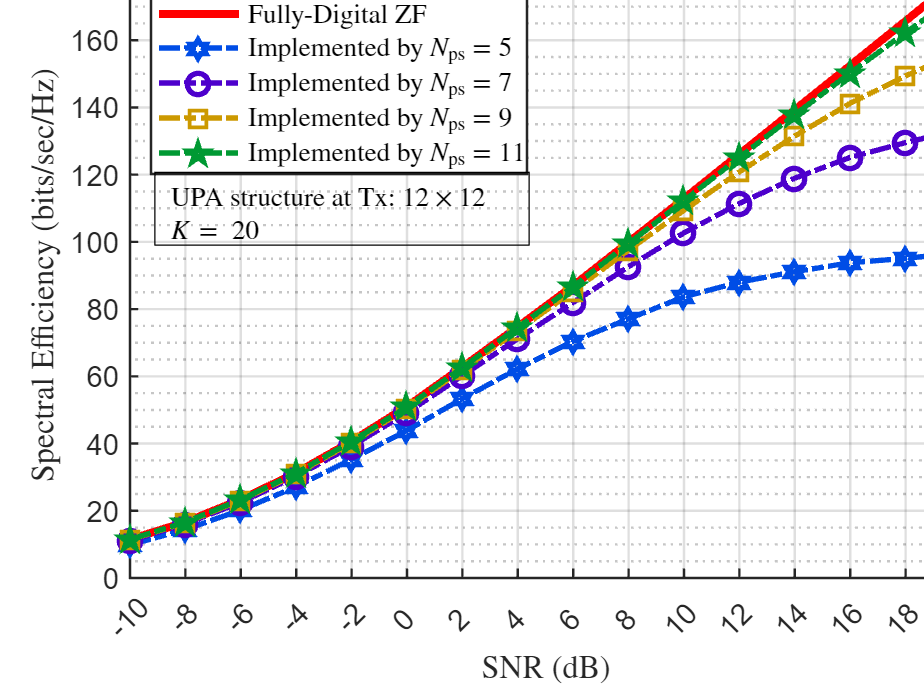

Data1= sum(SumR_ZF,2)/realization;
Data2= sum(R_ZF1,2)/realization;
Data3= sum(R_ZF2,2)/realization;
Data4= sum((R_ZF3),2)/realization;
Data5= sum((R_ZF4),2)/realization;
%% plot 

Xaxis= SNR_dB;
Fig=figure;
hold on
P1=plot(Xaxis,Data1);
P2=plot(Xaxis,Data2);
P3=plot(Xaxis,Data3);
P4=plot(Xaxis,Data4);
P5=plot(Xaxis,Data5);


Legend1='Fully-Digital ZF';
Legend2=['Implemented by $N_{\mathrm{ps}}=$',num2str(NPS(1))];
Legend3=['Implemented by $N_{\mathrm{ps}}=$',num2str(NPS(2))];
Legend4=['Implemented by $N_{\mathrm{ps}}=$',num2str(NPS(3))];
Legend5=['Implemented by $N_{\mathrm{ps}}=$',num2str(NPS(4))];

% Legend4='Proposed Hybrid BF Alg for $b=1$, $N_{RF}=N_s+3 $';
% Legend5=' Quantized-Hybrid BF in [31] (OMP)';

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','none');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',3);
set(P1,'Color','r');
set(P1,'MarkerSize',7);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 0.3 0.9]);
set(P2,'MarkerSize',7);
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% P2 properties
set(P3,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','o');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[0.3 .0 0.8]);
set(P3,'MarkerSize',8);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% P2 properties
set(P4,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P4,'Marker','s');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P4,'LineWidth',2);
set(P4,'Color',[.8 0.6 0.0]);
set(P4,'MarkerSize',8);
P4_group= hggroup;set(P4,'Parent',P4_group);
set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% % P2 properties
set(P5,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P5,'Marker','pentagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P5,'LineWidth',2);
set(P5,'Color',[0 .6 .2]);
set(P5,'MarkerSize',7);
P5_group= hggroup;set(P5,'Parent',P5_group);
set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');



lgd=legend(Legend1,Legend2,Legend3,Legend4,Legend5);
% Axes Properties 
ax=gca;
ax.XLim = [min(Xaxis) max(Xaxis)];
% ax.YLim = [0 50];
ax.XTick = Xaxis;
% ax.YTick = 0:5:50;
ax.XTickLabel=Xaxis;
ax.XLabel.String='SNR (dB)';
ax.YLabel.String='Spectral Efficiency (bits/sec/Hz)';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'northwest'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ ax.TightInset(4)+ ax.Position(4))];

%%  Creat notation 
Not1=annotation('textbox');
X_points=[ .03*(diff(ax.XLim)) .48*(diff(ax.XLim))]+ax.XLim(1);
Y_points=[ .55*(diff(ax.YLim)) .67*(diff(ax.YLim))]+ax.YLim(1);
str1=['UPA structure at Tx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str2=['$N_{\mathrm{cl}}=$ ',num2str(Ncl),',  $N_{\mathrm{ray}}=$ ',num2str(Nray)];
str3=['$K=$ ',num2str(K)];
% str5=['$b=$',num2str(b)];
Not1.String={str1,str3};
Not1.FontSize = 10;
Not1.Interpreter='latex';
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];

% % 
% Ell=annotation('ellipse');
% X_points=[19 21];
% Y_points=[25 55];
% Ell.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Ell.Position=[x_begin y_begin  x_End y_End];
% 
% Textarrow1=annotation('textarrow');
% X_points=[8 8];
% Y_points=[30 62];
% str1=['$b_{ps}^{t}=b_{ps}^{r}=\infty$'];
% Textarrow1.String={str1};
% Textarrow1.Interpreter='latex';
% Textarrow1.FontSize = 10;
% Textarrow1.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow1.Position=[x_begin y_begin  x_End y_End];
% %%
% Ell2=annotation('ellipse');
% X_points=[19 21];
% Y_points=[90 125];
% Ell2.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Ell2.Position=[x_begin y_begin  x_End y_End];
% 
% Textarrow2=annotation('textarrow');
% X_points=[16 16];
% Y_points=[30 81];
% str1=['$b_{ps}^{t}=b_{ps}^{r}=$',num2str(B_Vec{2})];
% Textarrow2.String={str1};
% Textarrow2.Interpreter='latex';
% Textarrow2.FontSize = 10;
% Textarrow2.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow2.Position=[x_begin y_begin  x_End y_End];
% %%
% Ell3=annotation('ellipse');
% X_points=[19 21];
% Y_points=[140 185];
% Ell3.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Ell3.Position=[x_begin y_begin  x_End y_End];
% 
% Textarrow3=annotation('textarrow');
% X_points=[24 24];
% Y_points=[30 90];
% str1=['$b_{ps}^{t}=b_{ps}^{r}=$',num2str(B_Vec{3})];
% Textarrow3.String={str1};
% Textarrow3.Interpreter='latex';
% Textarrow3.FontSize = 10;
% Textarrow3.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow3.Position=[x_begin y_begin  x_End y_End];